clc;
clear;

num_armax = [1 0.08774];
den_armax = [1 0.01213];
k = 100.0;

% Closed-loop transfer function
tf_t_closed = tf( k*num_armax, den_armax)

tf_t_closed =
 
  100 s + 8.774
  -------------
   s + 0.01213
 
Continuous-time transfer function.
Model Properties


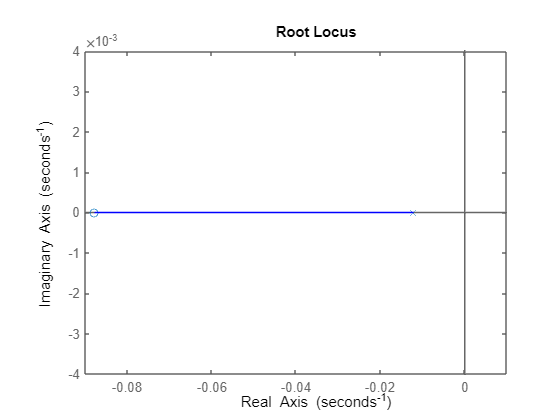

rlocus(tf_t_closed)


result = c2d(tf_t_closed, 1/100, "zoh")

result =
 
  100 z - 99.91
  -------------
   z - 0.9999
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties
